Inicializamos a toolbox para iniciar o projeto

startup_rvc;

Robotics, Vision & Control: (c) Peter Corke 1992-2011 http://www.petercorke.com
- Robotics Toolbox for MATLAB (release 10.2)
 - ARTE contributed code: 3D models for robot manipulators (C:\Users\ricar\Downloads\robot-10.2\rvctools\robot\data\ARTE)
 - pHRIWARE (release 1.1): pHRIWARE is Copyrighted by Bryan Moutrie (2013-2019) (c)


Conectamos os nós remotos do ROS e inicializamos o ambiente

setenv('ROS_MASTER_URI','http://10.0.0.103:11311')
setenv('ROS_IP','10.0.0.103')

rosinit;

The value of the ROS_MASTER_URI environment variable, http://10.0.0.103:11311, will be used to connect to the ROS master.
The value of the ROS_IP environment variable, 10.0.0.103, will be used to set the advertised address for the ROS node.


Cannot connect to ROS master at http://10.0.0.103:11311. Check the specified address or hostname.

Recebemos as posições do cubo pelo ROS e colocamos na varíável my_sub

sub = rossubscriber('/denso_cube_tf');
my_sub= receive(sub, 10);

Criação dos link para o braço de 6 juntas. Utilizamos a função Revolute para criar 6 juntas rotacionais para nosso robô.

%% Criação dos Links para o braço de 6-juntas
L(1) = Revolute('a', 0, 'alpha', pi/2, 'd', 0.125, 'qlim', [-2.79, 2.79]);
L(2) = Revolute('a', 0.21, 'alpha', 0, 'd', 0, 'offset', pi/2, 'qlim', [-2.09, 2.09]);
L(3) = Revolute('a', -0.075, 'alpha', -pi/2, 'd', 0, 'offset', -pi/2, 'qlim', [0.33, 2.79]);
L(4) = Revolute('a', 0, 'alpha', pi/2, 'd', 0.21, 'qlim', [-2.79, 2.79]);
L(5) = Revolute('a', 0, 'alpha', -pi/2, 'd', 0, 'qlim', [-2.09, 2.09]);
L(6) = Revolute('a', 0, 'alpha', 0, 'd', 0.07, 'qlim', [-6.28, 6.28]);

Criamos um objeto SerialLink com os links gerados anteriormente e setamos ums posição inicial para o denso no espaço de juntas.

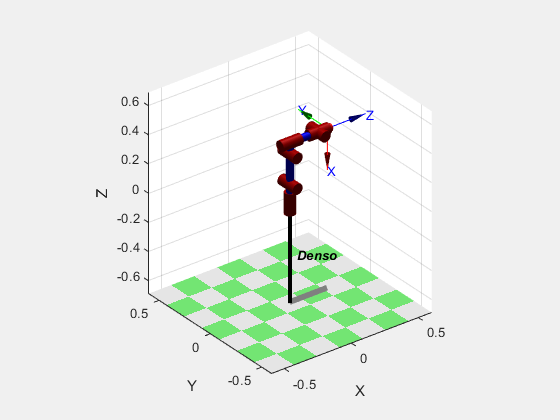

robot = SerialLink(L, 'name', 'Denso');
q = [0 0 -pi/2 0 0 0];
robot.plot(q)

Em seguida calculamos as cinemáticas direta e inversa para a configuração incial para verificar se os valores congruem. 

Kd = robot.fkine(q)

 

Kd = 
         0         0         1      0.28
         0         1         0         0
        -1         0         0      0.41
         0         0         0         1



Ki = robot.ikunc(Kd)

Ki =    -0.0000   -0.0000   -1.5708   -0.0000   -0.0000    0.0000


Como medida de segurança calculamos pontos para a trajetória para que o braço não bata no cubo, o prosicionando inicialmente acima do cubo. Para fins de simulação os valores para t1, t2 e t3 podem ser encontrados utilizando a função teach e depois setados nos valores de x, y, z e na matriz de rotação.

%robot.teach()
x1 = my_sub.Transforms.Transform.Translation.X + 0.1;
y1 = my_sub.Transforms.Transform.Translation.Y + 0.02;
z1 = my_sub.Transforms.Transform.Translation.Z - 0.025 + 0.25 - 0.115;
t1 = transl(x1, y1, z1+0.15);
t1(1:3,1:3) = [-1 0 0;0 1 0;0 0 -1];
%Ponto no meio do cubo
x2 = my_sub.Transforms.Transform.Translation.X + 0.1;
y2 = my_sub.Transforms.Transform.Translation.Y + 0.02;
z2 = my_sub.Transforms.Transform.Translation.Z - 0.025 + 0.19 - 0.115;
t2 = transl(x2, y2, z2+0.15);
t2(1:3,1:3) = [-1 0 0;0 1 0;0 0 -1];
%Ponto goal
x3 = 0.2;
y3 = 0.155;
z3 = -0.088;
t3 = transl(x3,y3,z3+0.15);
t3(1:3,1:3) = [-1 0 0;0 1 0;0 0 -1];
%Cinematica inversa
Ki1 = robot.ikunc(t1);
Ki2 = robot.ikunc(t2);
Ki3 = robot.ikunc(t3);

Exemplo para simulação:

%robot.teach()
%Ponto acima do cubo
x1 = 0.398 + 0.1;
y1 = 0.02;
z1 = 0.05 - 0.025 + 0.25 - 0.115; 
t1 = transl(x1, y1, z1+0.15);
t1(1:3,1:3) = [-1 0 0;0 1 0;0 0 -1];
t1

t1 =    -1.0000         0         0    0.4980
         0    1.0000         0    0.0200
         0         0   -1.0000    0.3100
         0         0         0    1.0000



%Ponto no meio do cubo
x2 = 0.398 + 0.1;
y2 = 0.02;
z2 = 0.05 - 0.025 - 0.115;
t2 = transl(x2, y2, z2+0.15);
t2(1:3,1:3) = [-1 0 0;0 1 0;0 0 -1];
t2

t2 =    -1.0000         0         0    0.4980
         0    1.0000         0    0.0200
         0         0   -1.0000    0.0600
         0         0         0    1.0000



%Ponto final
x3 = 0.326;
y3 = -0.230;
z3 = -0.088;
t3 = transl(x3,y3,z3+0.15);
t3(1:3,1:3) = [-1 0 0;0 1 0;0 0 -1];
t3

t3 =    -1.0000         0         0    0.3260
         0    1.0000         0   -0.2300
         0         0   -1.0000    0.0620
         0         0         0    1.0000


Em seguida calculamos as cinemáticas inversas dos pontos para ter os espaços de juntas

%Cinematica inversa
Ki1 = robot.ikunc(t1)

Ki1 =     0.0401   -1.0939   -0.3430    0.0000   -1.6302    0.0401


Ki2 = robot.ikunc(t2)

Ki2 =     0.0401   -1.5608   -0.3430   -0.0000   -1.1964    0.0401


Ki3 = robot.ikunc(t3)

Ki3 =    -0.6144   -1.1417   -1.1408   -0.0000   -0.8591   -0.6144


Aqui plotamos os pontos de cada trajetória com as posições do braço

robot.plot(q);

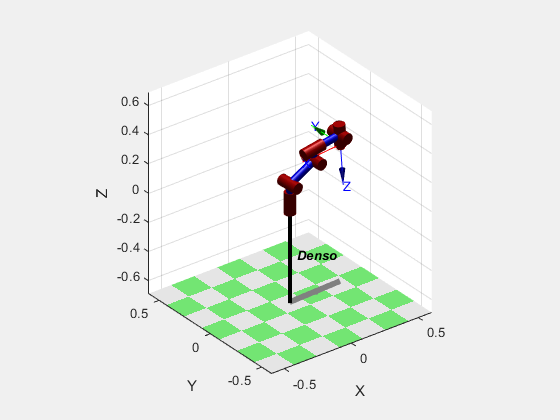

robot.plot(Ki1);

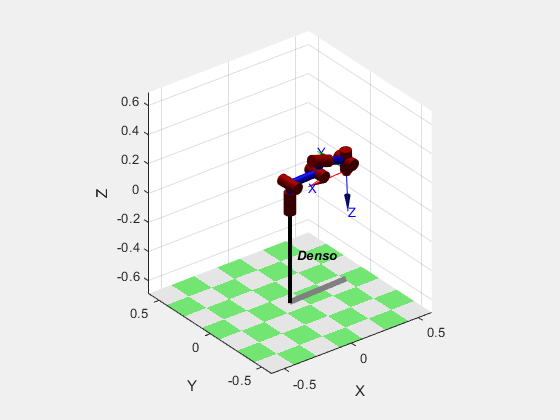

robot.plot(Ki2);

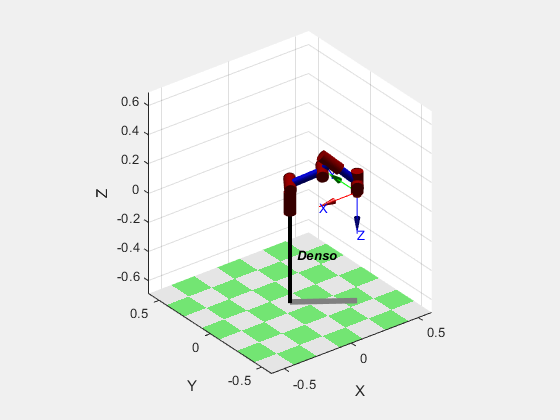

robot.plot(Ki3);

Agora vamos calcular as trajetórias para pegar o cubo e colocar em outra localidade, essas trajetórias serão enviadas para o denso como angulos por cinemática inversa

t = 50;
traj = jtraj(q, Ki1, t)

traj =          0         0   -1.5708         0         0         0
    0.0000   -0.0001   -1.5707    0.0000   -0.0001    0.0000
    0.0000   -0.0007   -1.5700    0.0000   -0.0010    0.0000
    0.0001   -0.0023   -1.5682    0.0000   -0.0034    0.0001
    0.0002   -0.0052   -1.5649    0.0000   -0.0078    0.0002
    0.0004   -0.0099   -1.5597    0.0000   -0.0148    0.0004
    0.0006   -0.0166   -1.5522    0.0000   -0.0247    0.0006
    0.0009   -0.0254   -1.5422    0.0000   -0.0379    0.0009
    0.0013   -0.0367   -1.5296    0.0000   -0.0547    0.0013
    0.0019   -0.0505   -1.5141    0.0000   -0.0752    0.0019


traj2 = jtraj(Ki1, Ki2, t)

traj2 =     0.0401   -1.0939   -0.3430    0.0000   -1.6302    0.0401
    0.0401   -1.0940   -0.3430    0.0000   -1.6302    0.0401
    0.0401   -1.0942   -0.3430    0.0000   -1.6299    0.0401
    0.0401   -1.0949   -0.3430    0.0000   -1.6293    0.0401
    0.0401   -1.0962   -0.3430    0.0000   -1.6281    0.0401
    0.0401   -1.0982   -0.3430    0.0000   -1.6263    0.0401
    0.0401   -1.1010   -0.3430    0.0000   -1.6237    0.0401
    0.0401   -1.1048   -0.3430    0.0000   -1.6201    0.0401
    0.0401   -1.1096   -0.3430    0.0000   -1.6157    0.0401
    0.0401   -1.1155   -0.3430    0.0000   -1.6102    0.0401


traj3 = jtraj(Ki2, q, t)

traj3 =     0.0401   -1.5608   -0.3430   -0.0000   -1.1964    0.0401
    0.0401   -1.5607   -0.3431   -0.0000   -1.1963    0.0401
    0.0401   -1.5598   -0.3438   -0.0000   -1.1956    0.0401
    0.0401   -1.5576   -0.3456   -0.0000   -1.1939    0.0401
    0.0399   -1.5533   -0.3489   -0.0000   -1.1906    0.0399
    0.0398   -1.5467   -0.3542   -0.0000   -1.1855    0.0398
    0.0395   -1.5372   -0.3616   -0.0000   -1.1782    0.0395
    0.0392   -1.5245   -0.3716   -0.0000   -1.1685    0.0392
    0.0388   -1.5084   -0.3842   -0.0000   -1.1562    0.0388
    0.0383   -1.4888   -0.3997   -0.0000   -1.1412    0.0383


traj4 = jtraj(q, Ki3, t)

traj4 =          0         0   -1.5708         0         0         0
   -0.0001   -0.0001   -1.5708   -0.0000   -0.0001   -0.0001
   -0.0004   -0.0007   -1.5705   -0.0000   -0.0005   -0.0004
   -0.0013   -0.0024   -1.5699   -0.0000   -0.0018   -0.0013
   -0.0029   -0.0055   -1.5687   -0.0000   -0.0041   -0.0029
   -0.0056   -0.0103   -1.5669   -0.0000   -0.0078   -0.0056
   -0.0093   -0.0173   -1.5643   -0.0000   -0.0130   -0.0093
   -0.0143   -0.0266   -1.5608   -0.0000   -0.0200   -0.0143
   -0.0206   -0.0383   -1.5564   -0.0000   -0.0288   -0.0206
   -0.0284   -0.0527   -1.5510   -0.0000   -0.0396   -0.0284


traj5 = jtraj(Ki3, q, t)

traj5 =    -0.6144   -1.1417   -1.1408   -0.0000   -0.8591   -0.6144
   -0.6144   -1.1416   -1.1408   -0.0000   -0.8590   -0.6144
   -0.6140   -1.1410   -1.1411   -0.0000   -0.8585   -0.6140
   -0.6131   -1.1393   -1.1417   -0.0000   -0.8573   -0.6131
   -0.6115   -1.1362   -1.1429   -0.0000   -0.8550   -0.6115
   -0.6089   -1.1314   -1.1447   -0.0000   -0.8513   -0.6089
   -0.6051   -1.1244   -1.1473   -0.0000   -0.8461   -0.6051
   -0.6001   -1.1152   -1.1508   -0.0000   -0.8391   -0.6001
   -0.5938   -1.1034   -1.1552   -0.0000   -0.8302   -0.5938
   -0.5861   -1.0890   -1.1606   -0.0000   -0.8194   -0.5861


trajF = [traj;traj2;traj3;traj4;traj5];

E plotamos o robô atuando nestas trajetórias(Rodar no scrpt ou livescript do matlab melhora a visualização):

%Trajetória inicial=>acima do cubo
for i = 1:1:t
    [traj(i,1) traj(i,2) traj(i,3) traj(i,4) traj(i,5) traj(i,6)];
    robot.plot([traj(i,1) traj(i,2) traj(i,3) traj(i,4) traj(i,5) traj(i,6)])
    pause(0.01);
end

%Trajetória acima do cubo=>pegar cubo
for i = 1:1:t
    [traj2(i,1) traj2(i,2) traj2(i,3) traj2(i,4) traj2(i,5) traj2(i,6)];
    robot.plot([traj2(i,1) traj2(i,2) traj2(i,3) traj2(i,4) traj2(i,5) traj2(i,6)])
    pause(0.01);
end

%Trajetória pegar cubo=>inicial(com cubo)
for i = 1:1:t
    [traj3(i,1) traj3(i,2) traj3(i,3) traj3(i,4) traj3(i,5) traj3(i,6)];
    robot.plot([traj3(i,1) traj3(i,2) traj3(i,3) traj3(i,4) traj3(i,5) traj3(i,6)])
    pause(0.01);
end

%Trajetória inicial(com cubo)=>objetivo(solta cubo)
for i = 1:1:t
    [traj4(i,1) traj4(i,2) traj4(i,3) traj4(i,4) traj4(i,5) traj4(i,6)];
    robot.plot([traj4(i,1) traj4(i,2) traj4(i,3) traj4(i,4) traj4(i,5) traj4(i,6)])
    pause(0.01);
end

Aqui vamos enviar os parâmetros para o robô através de variáveis que vão para o simulink

for i = 1:1:t*5
    stheta1 = num2str(trajF(i,1));
    stheta2 = num2str(trajF(i,2));
    stheta3 = num2str(trajF(i,3));
    stheta4 = num2str(trajF(i,4));
    stheta5 = num2str(trajF(i,5));
    stheta6 = num2str(trajF(i,6));
    pause(0.1)
    set_param('projetoRobotica/theta1','Value',stheta1);
    set_param('projetoRobotica/theta2','Value',stheta2);
    set_param('projetoRobotica/theta3','Value',stheta3);
    set_param('projetoRobotica/theta4','Value',stheta4);
    set_param('projetoRobotica/theta5','Value',stheta5);
    set_param('projetoRobotica/theta6','Value',stheta6);
    % Ao chegar no cubo passamos este valor para a garra fechar
    if i == t*2
        set_param('projetoRobotica/gripper','Value','0.43');
        pause(3)
    end
    % Ao chegar no objetivo passamos este valor para a garra abrir
    if i == t*4
        set_param('projetoRobotica/gripper','Value','0');
        pause(3)
    end
    
end